clear
MA = readmatrix("计数数据3_1.8s_2.3s_2hB.csv");
MB = readmatrix("计数数据1_1s_1.5s_1hB.csv");
NA = MA(3:end,1);
chA = MA(3:end,3);
NB = MB(3:end,1);
chB = MB(3:end,3);
%hold on
%plot(NA,log(chA))
% plot(NB,log(chB))
% legend('ch1','ch2')

[cha,a1,b1] = find(chA);
[chb,a2,b2] = find(chB);

CHA = chA(a1:b1) - mean(cha);
CHB = chB(a2:b2) - mean(chb);
% CHA1 = zeros(length(chA),1);
% CHA1(a1:b1) = CHA;
% plot(1:b1 - a1 + 1,log(CHA))

f = fit((180:b1 - a1 + 1)',log(CHA(180:end)),'poly1')

f =      线性模型 Poly1:
     f(x) = p1*x + p2
     系数(置信边界为 95%):
       p1 =  -0.0005636  (-0.0005881, -0.0005391)
       p2 =       9.811  (9.805, 9.818)

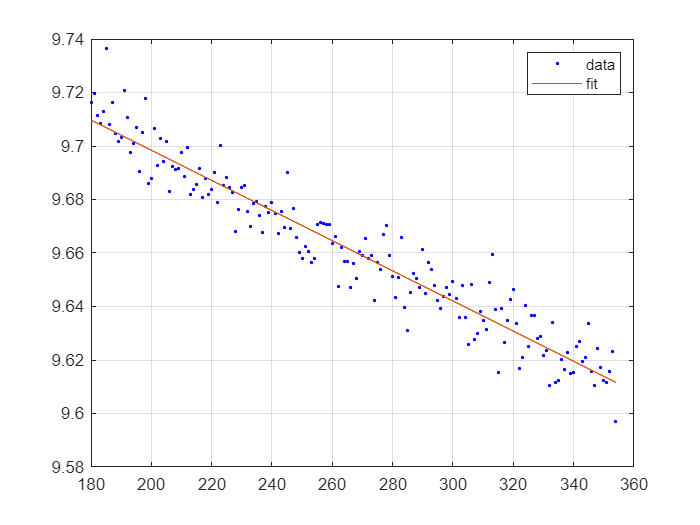

NNA = 1:b1 - a1 + 1;
hold on
scatter(180:b1 - a1 + 1,log(CHA(180:end)),'blue','.')
plot(180:b1 - a1 + 1,f(180:b1 - a1 + 1))
x = 180:b1 - a1 + 1;
grid on
box on
legend("data","fit")

%xlim([0 b1 - a1 + 1])

function [chh,head,tail] = find(A)
    i1 = 0;
    while A(i1 + 1) < 1000
        i1 = i1 + 1;
    end
    i2 = ceil(length(A)/2);
    while A(i2) > 1000
        i2 = i2 + 1;
    end
    chh = [A(1:i1); A(i2:end)];
    head = i1 + 1;
    tail = i2 - 1;
end

function ind = FindIndex(a,b,A,cri)  %分治
    head = A(a) - cri;
    head = head/abs(head);
    tail = A(b) - cri;
    tail = tail/abs(tail);
    if head == tail
        ind = -1;  %最后回溯的条件
        return
    else
        re1 = FindIndex(a,floor((a + b)/2),A,cri);  %再分
        re2 = FindIndex(floor((a + b)/2) + 1,b,A,cri);
        if re1 == re2
            ind = floor((a + b)/2);
            return
        else
            if re1 > re2
                ind = re1;
                return
            else
                ind = re2;
                return
            end
        end
    end
end